# Logistic Regression(Classification)

## 1 Load the Data

x = load('ex4x.dat');
y = load('ex4y.dat');

**Load the data for the training examplings to programmer and add the x0=1 intercept term into the x matrix**

n = length(x);
X = [ones(n,1), x];

## 2 Plot the data

**Before beginning Newton's Method, we will first plot the data using different symbols to represent the two classes**

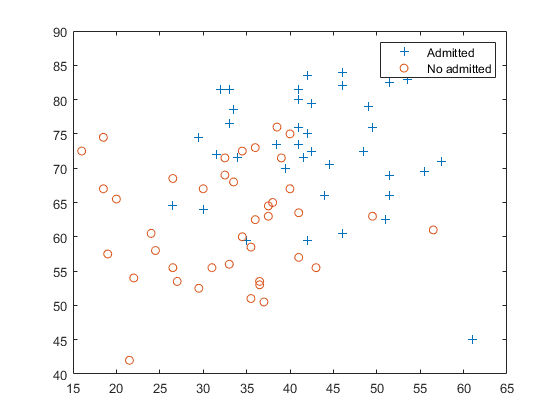

%find returns the indices of the rows meeting the specified condition
pos = find(y==1);
neg = find(y==0);
% pos
% neg
% Assume the features are in the 2nd and 3rd coluns of x
plot(X(pos,2),X(pos,3),'+');
hold on
plot(X(neg,2),X(neg,3),'o')
legend('Admitted','No admitted')
hold off

**数据维数注意**

X(1,:)

ans =     1.0000   55.5000   69.5000


[n,m]=size(transpose(X))

n = 3

m = 80

## 3 Newton method

% 基本参数
iterMax = 8;
[theta,J] = Newton_model(X,y,iterMax)

theta =   -16.3787
    0.1483
    0.1589


J =     0.6931
    0.4409
    0.4089
    0.4055
    0.4054
    0.4054
    0.4054
    0.4054


**Plot the Decision boundary**

y = (-1/theta(3)).*(theta(2).*X(:,2)+theta(1))

y =    51.2612
   64.7969
   53.1281
   60.1294
   64.7969
   54.9951
   55.4619
   63.8634
   53.1281
   49.3942


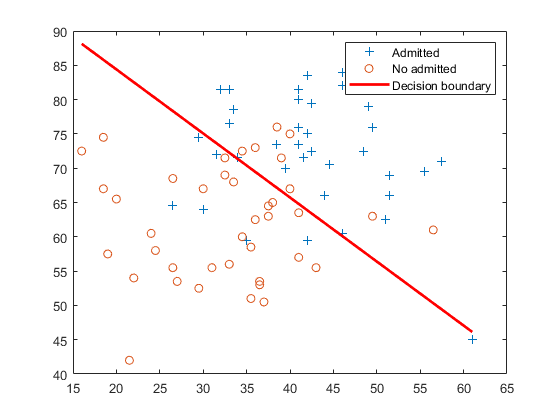

plot(X(pos,2),X(pos,3),'+');
hold on
plot(X(neg,2),X(neg,3),'o')
plot(X(:,2),y,'r','LineWidth',2)
legend('Admitted','No admitted','Decision boundary')
hold off

**Plot the J(\theta)**

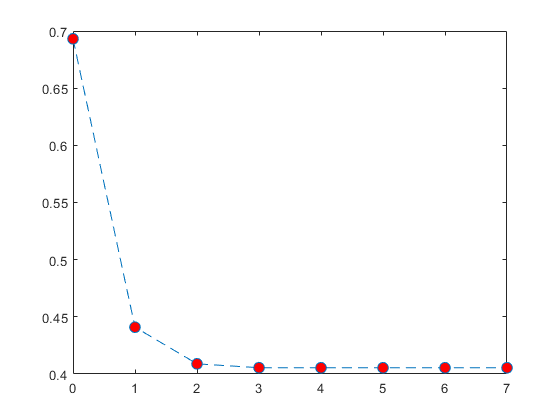

x_j = 0:iterMax-1;
plot(x_j,J,'o--', 'MarkerFaceColor', 'r', 'MarkerSize', 8)